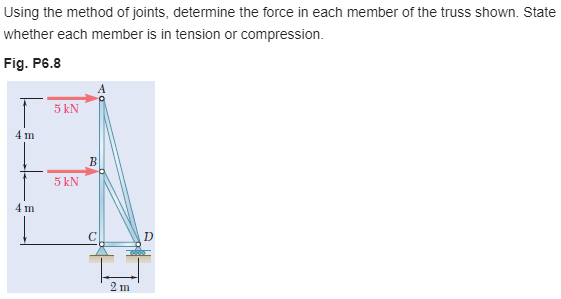

[https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-8P-solution-9780077687304](https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-8P-solution-9780077687304) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# member data

E = sym('E');
A = sym('A');
thetaAD = atand(sym(8)/sym(2))*u.deg;
thetaBD = atand(sym(4)/sym(2))*u.deg;

# truss

t = Truss;
t = t.add('reaction', {'Rcx' 'Rcy'}, [0 -8]*u.m);
t = t.add('reaction', {0 'Rdy'}, [2 -8]*u.m);
t = t.add('concentrated', [5 0]*u.kN, [0 0]);
t = t.add('concentrated', [5 0]*u.kN, [0 -4]*u.m);
t = t.add('joint', 'A', [0 0]);
t = t.add('joint', 'B', [0 -4]*u.m);
t = t.add('joint', 'C', [0 -8]*u.m);
t = t.add('joint', 'D', [2 -8]*u.m);
t = t.add('member', 'Fab', [0 0], [0 -4]*u.m);
t = t.add('member', 'Fad', [0 0], [2 -8]*u.m);
t = t.add('member', 'Fbc', [0 -4]*u.m, [0 -8]*u.m);
t = t.add('member', 'Fbd', [0 -4]*u.m, [2 -8]*u.m);
t = t.add('member', 'Fcd', [0 -8]*u.m, [2 -8]*u.m);

# solution

[us ua fs fa rs ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua, 6) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & \frac{1520.93}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{1} & \frac{200.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{2} & \frac{371.803}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{2} & \frac{120.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{3} & 0\\ v_{3} & 0\\ u_{4} & \frac{20.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{4} & 0 \end{array}\right)$$

fa_vpa = vpa(fa, 4) %#ok

$$fa\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & 20.0\,\mathrm{kN}\\ \mathrm{Fad} & -20.62\,\mathrm{kN}\\ \mathrm{Fbc} & 30.0\,\mathrm{kN}\\ \mathrm{Fbd} & -11.18\,\mathrm{kN}\\ \mathrm{Fcd} & 10.0\,\mathrm{kN} \end{array}\right)$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Rcx} & -10\,\mathrm{kN}\\ \mathrm{Rcy} & -30\,\mathrm{kN}\\ \mathrm{Rdy} & 30\,\mathrm{kN} \end{array}\right)$$

# clean up

setassum(old_assum, 'clear');
clear ua_vpa fa_vpa old_assum;